# **Question 5.1:**

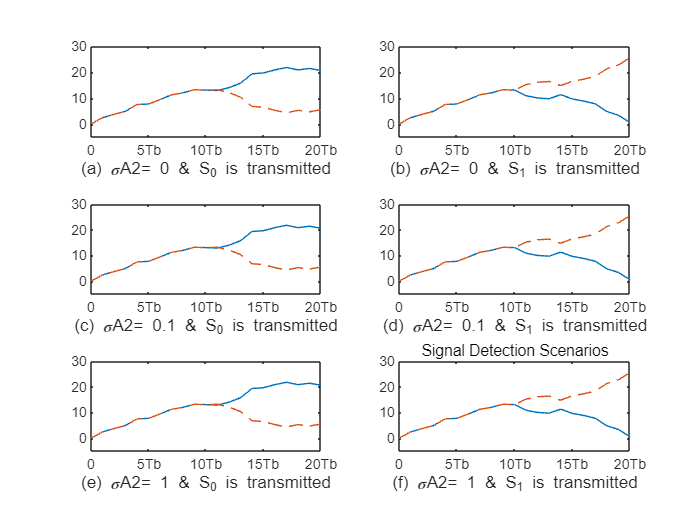

K = 20;
A = 1;
l = 0:K;
s0 = A * ones(1, K);
s1 = [A * ones(1, K/2), -A * ones(1, K/2)];

r0 = zeros(1, K);
r1 = zeros(1, K);
noise = randn(1, K);

s = s0;
r = s + noise; 

for n = 1:K
r0(n) = sum(r(1:n) .* s0(1:n));
r1(n) = sum(r(1:n) .* s1(1:n));
end

subplot(3, 2, 1)
plot(0:K, [0, r0], '-', 0:K, [0, r1], '--')
set(gca, 'XTickLabel', {'0', '5Tb', '10Tb', '15Tb', '20Tb'})
 
axis([0, 20, -5, 30])
xlabel('(a) \sigmaA2= 0 & S_{0} is transmitted', 'fontsize', 10)

s = s1;
r = s + noise; 

for n = 1:K
r0(n) = sum(r(1:n) .* s0(1:n));
r1(n) = sum(r(1:n) .* s1(1:n));
end

subplot(3, 2, 2)
plot(0:K, [0, r0], '-', 0:K, [0, r1], '--')
set(gca, 'XTickLabel', {'0', '5Tb', '10Tb', '15Tb', '20Tb'})
axis([0, 20, -5, 30])
xlabel('(b) \sigmaA2= 0 & S_{1} is transmitted', 'fontsize', 10)

0.1 * randn(1, K);

s = s0;
r = s + noise; 

for n = 1:K
r0(n) = sum(r(1:n) .* s0(1:n));
r1(n) = sum(r(1:n) .* s1(1:n));
end

subplot(3, 2, 3)
plot(0:K, [0, r0], '-', 0:K, [0, r1], '--')
set(gca, 'XTickLabel', {'0', '5Tb', '10Tb', '15Tb', '20Tb'})
axis([0, 20, -5, 30])
xlabel('(c) \sigmaA2= 0.1 & S_{0} is transmitted', 'fontsize', 10)

s = s1;
r = s + noise; 

for n = 1:K
r0(n) = sum(r(1:n) .* s0(1:n));
r1(n) = sum(r(1:n) .* s1(1:n));
end

subplot(3, 2, 4)
plot(0:K, [0, r0], '-', 0:K, [0, r1], '--')
set(gca, 'XTickLabel', {'0', '5Tb', '10Tb', '15Tb', '20Tb'})
axis([0, 20, -5, 30])
xlabel('(d) \sigmaA2= 0.1 & S_{1} is transmitted', 'fontsize', 10)

s = s0;
r = s + noise; 

for n = 1:K
r0(n) = sum(r(1:n) .* s0(1:n));
r1(n) = sum(r(1:n) .* s1(1:n));
end

subplot(3, 2, 5)
plot(0:K, [0, r0], '-', 0:K, [0, r1], '--')
set(gca, 'XTickLabel', {'0', '5Tb', '10Tb', '15Tb', '20Tb'})
axis([0, 20, -5, 30])
xlabel('(e) \sigmaA2= 1 & S_{0} is transmitted', 'fontsize', 10)

s = s1;
r = s + noise; 

for n = 1:K
r0(n) = sum(r(1:n) .* s0(1:n));
r1(n) = sum(r(1:n) .* s1(1:n));
end

subplot(3, 2, 6)
plot(0:K, [0, r0], '-', 0:K, [0, r1], '--')
set(gca, 'XTickLabel', {'0', '5Tb', '10Tb', '15Tb', '20Tb'})
axis([0, 20, -5, 30])
xlabel('(f) \sigmaA2= 1 & S_{1} is transmitted', 'fontsize', 10)

subtitle('Signal Detection Scenarios');

# **Question 5.2:**

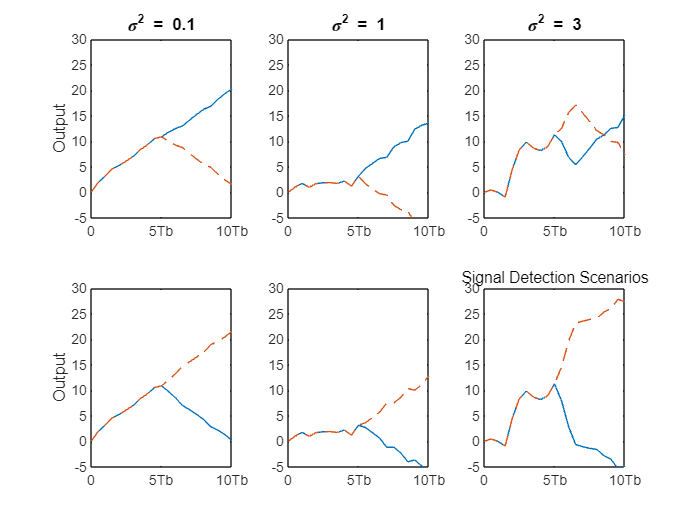

K = 20; 
A = 1;

l = 0:K;

s0 = A * ones(1, K);
s1 = [A * ones(1, K/2), -A * ones(1, K/2)];

r0 = zeros(1, K);r1 = zeros(1, K);

noise_variances = [0.1, 1, 3];

for var_idx = 1:length(noise_variances)

noise = sqrt(noise_variances(var_idx)) * randn(1, K);

s = s0;
r = s + noise; 

for n = 1:K
r0(n) = sum(r(1:n) .* s0(1:n));
r1(n) = sum(r(1:n) .* s1(1:n));
end

subplot(2, 3, var_idx)
plot(0:K, [0, r0], '-', 0:K, [0, r1], '--')
set(gca, 'XTickLabel', {'0', '5Tb', '10Tb', '15Tb', '20Tb'})
axis([0, 20, -5, 30])
title(['\sigma^2 = ' num2str(noise_variances(var_idx))], 'fontsize', 10)
if var_idx == 1 
    ylabel('Output', 'fontsize', 10)
end

s = s1;
r = s + noise; 

for n = 1:K
r0(n) = sum(r(1:n) .* s0(1:n));
r1(n) = sum(r(1:n) .* s1(1:n));
end

subplot(2, 3, var_idx + 3)
plot(0:K, [0, r0], '-', 0:K, [0, r1], '--')
set(gca, 'XTickLabel', {'0', '5Tb', '10Tb', '15Tb', '20Tb'})
axis([0, 20, -5, 30])
if var_idx == 1
ylabel('Output', 'fontsize', 10)
end
 
end

subtitle('Signal Detection Scenarios');

# **Question 5.3**

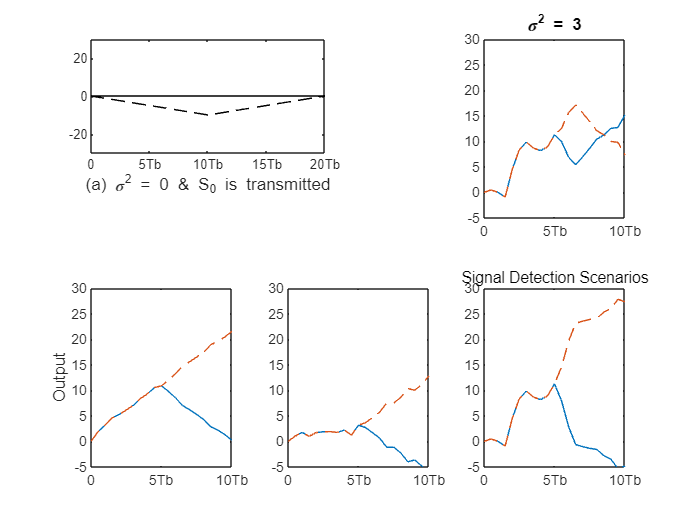

K = 20; 
A = 1;
l = 0:K;
s0 = A * ones(1, K);
s1 = [A * ones(1, K/2) -A * ones(1, K/2)];

y0 = zeros(1, K);
y1 = zeros(1, K);
 
noise = random('Normal', 0, 0, 1, K);

s = s0;
y = s + noise;
y1 = conv(y, fliplr(s1));

subplot(3, 2, 1);
plot(l, [0 y0(1:K)], '-k', l, [0 y1(1:K)], '--k');
set(gca, 'XTickLabel', {'0', '5Tb', '10Tb', '15Tb', '20Tb'});
axis([0 20 -30 30]);
xlabel('(a) \sigma^2 = 0 & S_0 is transmitted', 'fontsize', 10);

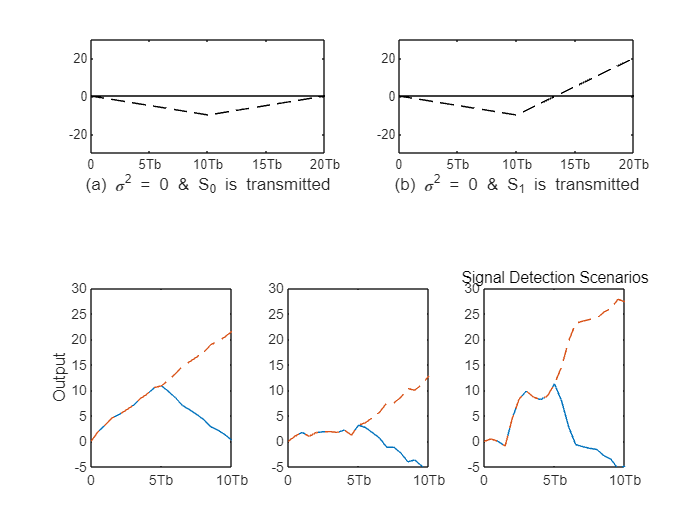

s = s1;
y = s + noise; 
y1 = conv(y, fliplr(s1));
subplot(3, 2, 2);
plot(l, [0 y0(1:K)], '-k', l, [0 y1(1:K)], '--k');
set(gca, 'XTickLabel', {'0', '5Tb', '10Tb', '15Tb', '20Tb'});
axis([0 20 -30 30]);
xlabel('(b) \sigma^2 = 0 & S_1 is transmitted', 'fontsize', 10);

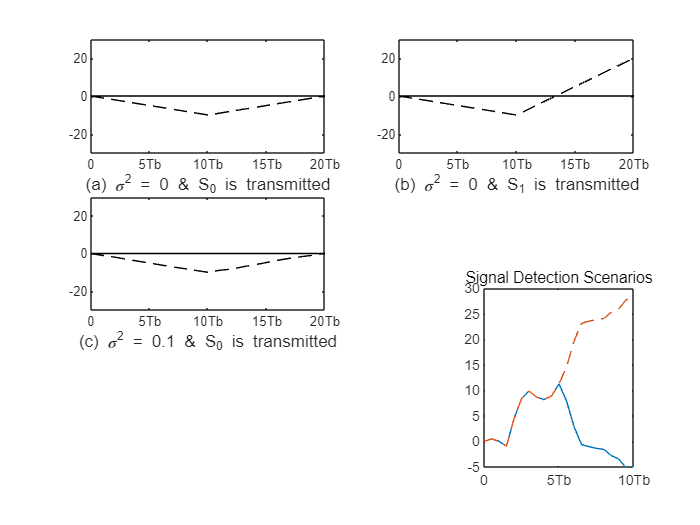

noise = random('Normal', 0, 0.1, 1, K);

s = s0;
y = s + noise; 
y1 = conv(y, fliplr(s1));
subplot(3, 2, 3);
plot(l, [0 y0(1:K)], '-k', l, [0 y1(1:K)], '--k');
set(gca, 'XTickLabel', {'0', '5Tb', '10Tb', '15Tb', '20Tb'});
axis([0 20 -30 30]);
xlabel('(c) \sigma^2 = 0.1 & S_0 is transmitted', 'fontsize', 10);

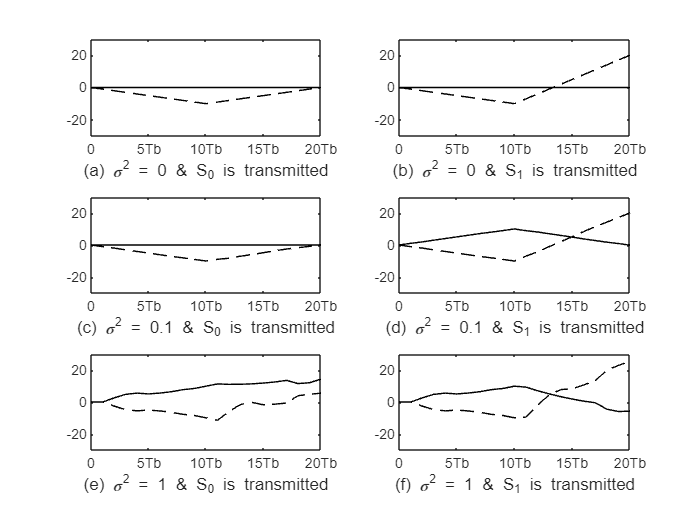

s = s1;
y = s + noise; 
y0 = conv(y, fliplr(s0));
y1 = conv(y, fliplr(s1));

subplot(3, 2, 4);
plot(l, [0 y0(1:K)], '-k', l, [0 y1(1:K)], '--k');
set(gca, 'XTickLabel', {'0', '5Tb', '10Tb', '15Tb', '20Tb'});
axis([0 20 -30 30]);
xlabel('(d) \sigma^2 = 0.1 & S_1 is transmitted', 'fontsize', 10);
noise = random('Normal', 0, 1, 1, K);

s = s0;
y = s + noise; 
y0 = conv(y, fliplr(s0));
y1 = conv(y, fliplr(s1));

subplot(3, 2, 5);
plot(l, [0 y0(1:K)], '-k', l, [0 y1(1:K)], '--k');
set(gca, 'XTickLabel', {'0', '5Tb', '10Tb', '15Tb', '20Tb'});
axis([0 20 -30 30]);
xlabel('(e) \sigma^2 = 1 & S_0 is transmitted', 'fontsize', 10);

s = s1;
y = s + noise; 
y0 = conv(y, fliplr(s0));
y1 = conv(y, fliplr(s1));

subplot(3, 2, 6);
plot(l, [0 y0(1:K)], '-k', l, [0 y1(1:K)], '--k');
set(gca, 'XTickLabel', {'0', '5Tb', '10Tb', '15Tb', '20Tb'});
axis([0 20 -30 30]);
xlabel('(f) \sigma^2 = 1 & S_1 is transmitted', 'fontsize', 10);

# **Question 5.4**

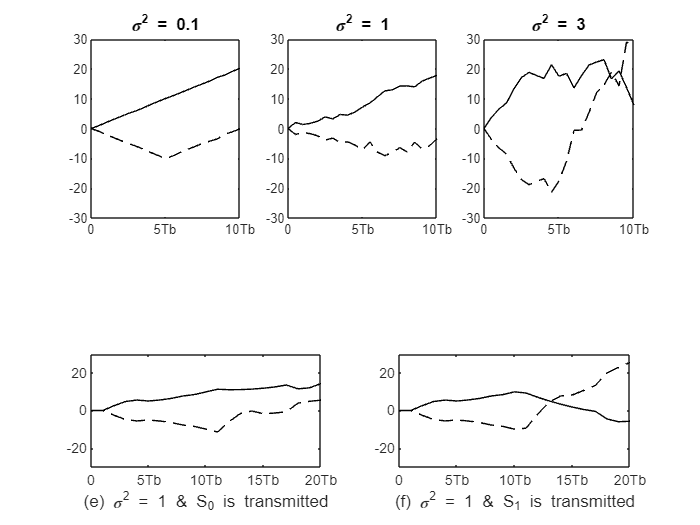

K = 20; 
A = 1;
l = 0:K;
s0 = A * ones(1, K);
s1 = [A * ones(1, K/2) -A * ones(1, K/2)];
variances = [0.1, 1, 3];

for var_idx = 1:length(variances)

y0 = zeros(1, K);
y1 = zeros(1, K);

variance = variances(var_idx);
noise = random('Normal', 0, variance, 1, K);

s = s0;
y = s + noise; 
y0 = conv(y, fliplr(s0));
y1 = conv(y, fliplr(s1));

subplot(2, length(variances), var_idx);
plot(l, [0 y0(1:K)], '-k', l, [0 y1(1:K)], '--k');
set(gca, 'XTickLabel', {'0', '5Tb', '10Tb', '15Tb', '20Tb'});
axis([0 20 -30 30]);
title(['\sigma^2 = ' num2str(variance)], 'fontsize', 10);

end

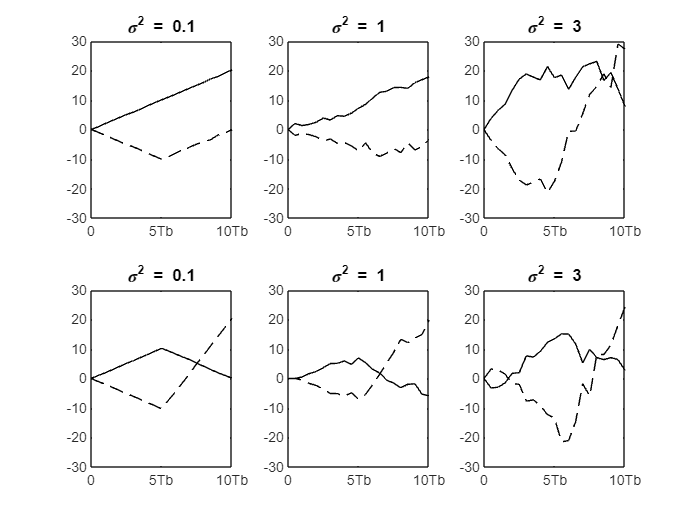

s = s1;
for var_idx = 1:length(variances)

y0 = zeros(1, K);
y1 = zeros(1, K);

variance = variances(var_idx);
noise = random('Normal', 0, variance, 1, K);

y = s + noise; 
y0 = conv(y, fliplr(s0));
y1 = conv(y, fliplr(s1)); 
subplot(2, length(variances), length(variances) + var_idx);plot(l, [0 y0(1:K)], '-k', l, [0 y1(1:K)], '--k');
set(gca, 'XTickLabel', {'0', '5Tb', '10Tb', '15Tb', '20Tb'});
axis([0 20 -30 30]);
title(['\sigma^2 = ' num2str(variance)], 'fontsize', 10);
end 